1 and 2.

o1=rank(obsv(sys1)) %if o1=4 system is obseravble, else not

o1 = 4

o2=rank(obsv(sys2)) %observable for q1,but not q2

o2 = 3

c1=rank(ctrb(sys1)) %if c1=4 system is controllable, else not

c1 = 4

c2=rank(ctrb(sys2)) %controllable for q1,but not q2

c2 = 4

3.

p =[-1 -0.5 -3 -2]

p =    -1.0000   -0.5000   -3.0000   -2.0000


K = place(A,B,p)

K =    -0.4582   41.1334   -1.7676   11.4676


4.

A1=A-B*K

A1 =          0         0    1.0000         0
         0         0         0    1.0000
    0.3055  -24.1489    1.1717   -7.6517
    0.3055  -14.3289    1.1717   -7.6717


sys1_lqr=ss(A1,B,C1,D)

sys1_lqr =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3  0.3055  -24.15   1.172  -7.652
   x4  0.3055  -14.33   1.172  -7.672
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



P=pole(sys1_lqr) %gives coordinates of poles of the system

P =    -3.0000
   -2.0000
   -1.0000
   -0.5000


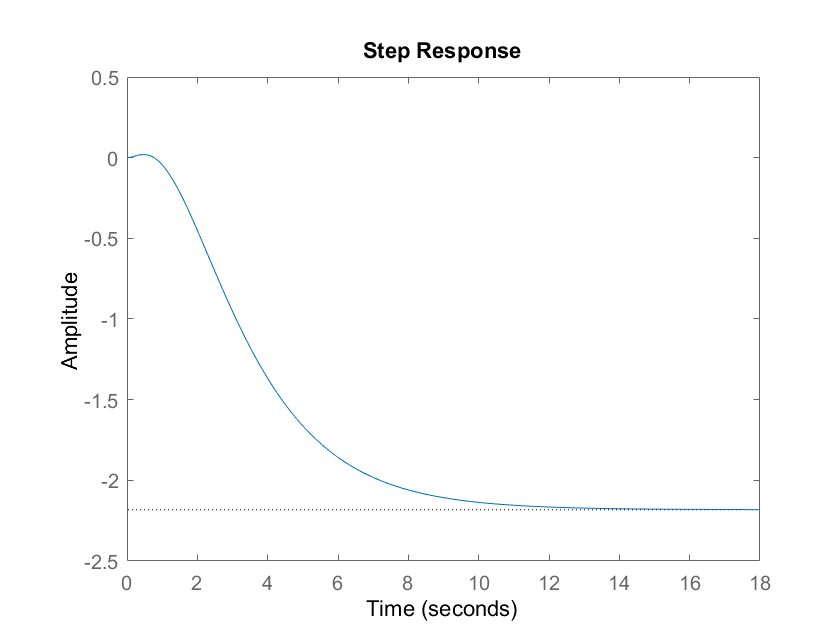

step(sys1_lqr) %plots step response

stable=isstable(sys1_lqr) %check if system is stable

stable = logical
   1


5.

p=[-2 -1 -2.5 -0.05]

p =    -2.0000   -1.0000   -2.5000   -0.0500


K= place(A,B,p)

K =    -0.0382   34.3574   -0.8464    9.1214


A1=A-B*K

A1 =          0         0    1.0000         0
         0         0         0    1.0000
    0.0255  -19.6316    0.5576   -6.0876
    0.0255   -9.8116    0.5576   -6.1076


sys1_lqr=ss(A1,B,C1,D)

sys1_lqr =
 
  A = 
            x1       x2       x3       x4
   x1        0        0        1        0
   x2        0        0        0        1
   x3  0.02546   -19.63   0.5576   -6.088
   x4  0.02546   -9.812   0.5576   -6.108
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



P=pole(sys1_lqr)

P =    -2.5000
   -2.0000
   -0.0500
   -1.0000


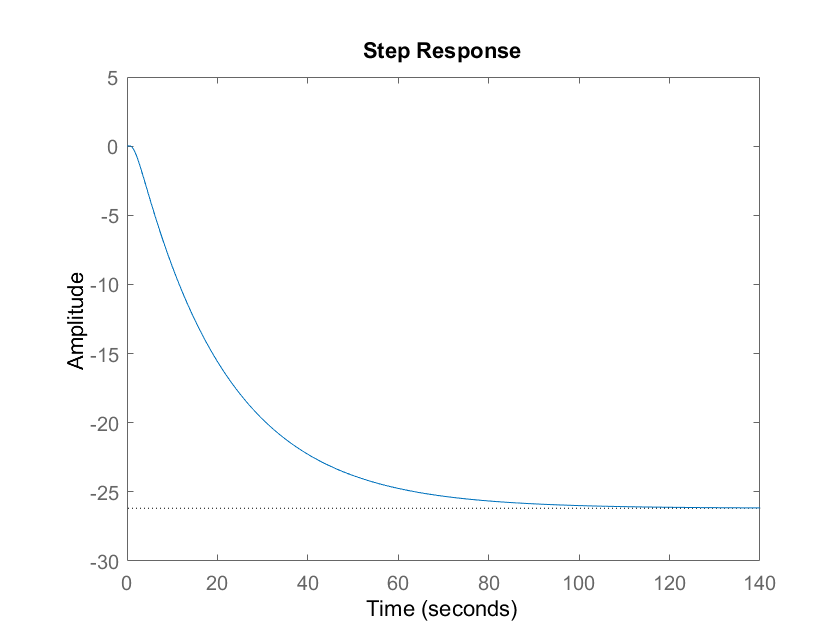

step(sys1_lqr)

stable=isstable(sys1_lqr)

stable = logical
   1


6.

Q=diag([0.05 2 1 0.001])

Q =     0.0500         0         0         0
         0    2.0000         0         0
         0         0    1.0000         0
         0         0         0    0.0010


R=0.0001

R = 1.0000e-04

N=[0;0;0;0]

N =      0
     0
     0
     0


K=lqr(sys1,Q,R,N)

K =   -22.3607  726.2565 -114.9796  224.9968


A1=A-B*K

A1 =          0         0    1.0000         0
         0         0         0    1.0000
   14.9071 -480.8977   76.6464 -150.0045
   14.9071 -471.0777   76.6464 -150.0245


sys1_lqr=ss(A1,B,C1,D)

sys1_lqr =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3   14.91  -480.9   76.65    -150
   x4   14.91  -471.1   76.65    -150
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



P=pole(sys1_lqr)

P =   -66.7339
   -3.9180
   -2.5025
   -0.2237


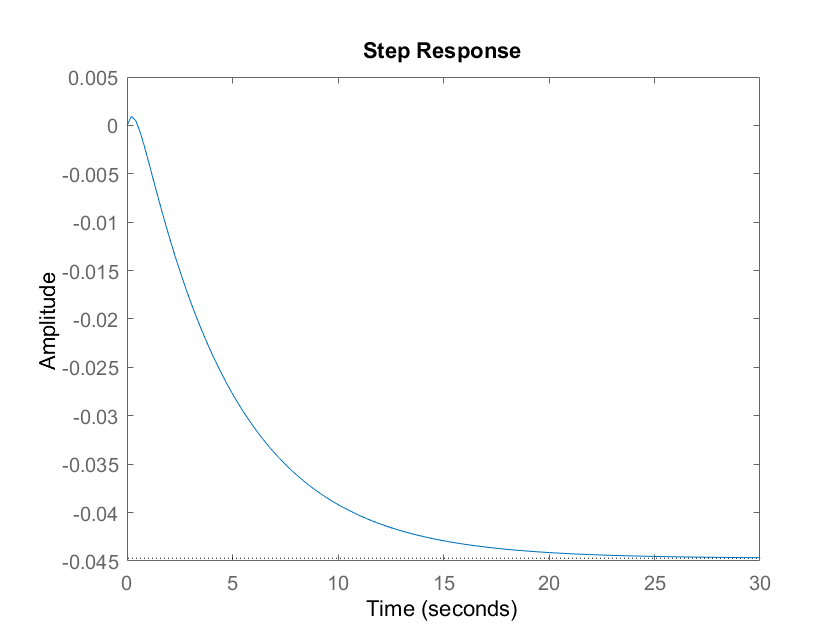

step(sys1_lqr)

Q=eye(c1)

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


R=50000

R = 50000

N=[0;0;0;0]

N =      0
     0
     0
     0


K=lqr(sys1,Q,R,N)

K =    -0.0045   40.0190   -0.1467   11.0528


A1=A-B*K

A1 =          0         0    1.0000         0
         0         0         0    1.0000
    0.0030  -23.4060    0.0911   -7.3752
    0.0030  -13.5860    0.0911   -7.3952


sys1_lqr=ss(A1,B,C1,D)

sys1_lqr =
 
  A = 
             x1        x2        x3        x4
   x1         0         0         1         0
   x2         0         0         0         1
   x3  0.002981    -23.41   0.09112    -7.375
   x4  0.002981    -13.59   0.09112    -7.395
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



P=pole(sys1_lqr)

P =   -3.6327 + 0.0000i
  -3.6043 + 0.0000i
  -0.0335 + 0.0333i
  -0.0335 - 0.0333i


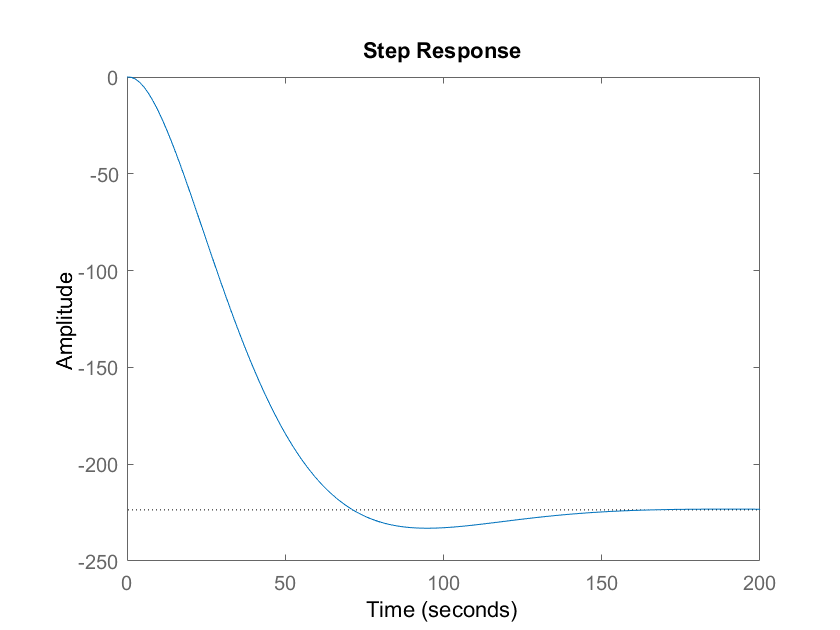

step(sys1_lqr)

stable=isstable(sys1_lqr)

stable = logical
   1
